# Time-Invariant System Identification Using Adaptive Filters

**Objective: **Performed a comparative system identification performance analysis of Variable-RLS and NLMS adaptive filters on an unknown time-invariant system excited by a coloured noise input.

**Conclusion: **Overall, the results confirm the expected behavior of adaptive filtering algorithms. For a time-invariant unknown system excited by coloured noise, both NLMS and variable-RLS successfully identify the system coefficients. However, variable-RLS provides faster convergence and lower MSE because it uses more information about the input signal correlation. NLMS converges more slowly, but it is simpler to implement and requires less computation. Therefore, the choice between both algorithms depends on the design requirement: RLS is preferred for rapid convergence, while NLMS is preferred when implementation simplicity and lower computational cost are more important.

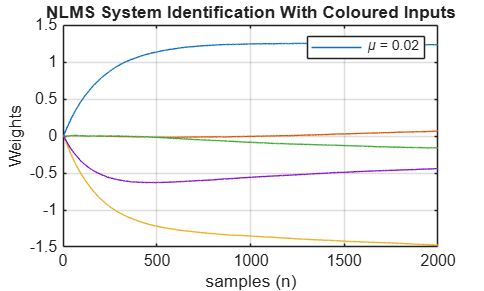

clear; clc;

%% =========================
%% NLMS PARAMETER SETUP
%% =========================
N = 2000;       % Number of samples
NumRuns = 50;   % Number of ensemble runs

% Unknown system
h = [1 0.5 -2 0 -0.4].';

% Adaptive Filter Length
M = length(h);

% NLMS Parameters
mu = 0.02;
delta_Nlms = 0.05;

% RLS Initialization Parameter
delta_Rls = 0.0005;

% Variable Forgetting Factor Parameters
lamda_init = 0.99;
lamda_min = 0.95;
lamda_max = 1.0;


%% =========================
%% COLORED INPUT FILTER
%% =========================
[Num,Den] = butter(10,0.6);

%% ==============================
%% INITIALIZE ENSEMBLE VARIABLES
%% ==============================
e_ensemble_nlms = zeros(N,1);
nWlms_ensemble = zeros(M,N+1);

e_ensemble_rls = zeros(N,1);
rls_weights_ensemble = zeros(M,N+1);

%% =========================
%% NLMS ALGORITHM
%% =========================
for i = 1:NumRuns

    % Generate white noise signal
    u = randn(N,1);

    % Generate measurement noise with variance 0.01
    v = sqrt(0.01)*randn(N,1);

    % Generate colored noise signal
    u = filter(Num,Den,u);

    % Normalize colored noise power
    u = u/std(u);

    % Desired signal
    d = filter(h,1,u) + v;

    % Initialize NLMS parameters
    nWlms = zeros(M,N+1);
    nlmsError = zeros(N,1);

    % Initialize RLS parameters
    rls_weights = zeros(M,N+1);
    uvector = zeros(M,1);
    xi = zeros(N,1);

    P = (1/delta_Rls)*eye(M);
    I = eye(M);

    lamda = lamda_init;

    g = zeros(M,N+1);
    s = zeros(M,M);

    % Update weights according to the NLMS algorithm
    for ii = M:N

        % Colored noise input vector
        uVector = u(ii:-1:ii-M+1);

        % NLMS error
        nlmsError(ii) = d(ii) - nWlms(:,ii)' * uVector;

        % NLMS weight update
        nWlms(:,ii+1) = nWlms(:,ii) + ...
            (mu/(delta_Nlms + uVector' * uVector)) * uVector * nlmsError(ii);

    end

    % Update weights according to the RLS algorithm
    for j = 1:N

        % Colored input vector
        uvector = [u(j); uvector(1:M-1)];

        % RLS gain vector
        pi_vec = P * uvector;
        k_vec = pi_vec / (lamda + uvector' * pi_vec);

        % Error
        xi(j) = d(j) - rls_weights(:,j)' * uvector;

        % RLS weight update
        rls_weights(:,j+1) = rls_weights(:,j) + k_vec * xi(j);

        % Inverse correlation matrix update
        P = (1/lamda) * (P - k_vec * uvector' * P);

        % Variable forgetting factor update
        lamda = lamda + delta_Rls * (g(:,j)' * uvector * xi(j));

        % Truncation of the forgetting factor
        if lamda_min < lamda && lamda < lamda_max

            s = (1/lamda) * (I - k_vec * uvector') * s * ...
                (I - uvector * k_vec') + ...
                (1/lamda) * ((k_vec * k_vec') - P);

            g(:,j+1) = (I - k_vec * uvector') * g(:,j) + ...
                s * uvector * xi(j);

        else

            lamda = min(max(lamda,lamda_min),lamda_max);

            s = zeros(M,M);
            g(:,j+1) = zeros(M,1);

        end
   end


    % Update ensemble averages
    e_ensemble_nlms = e_ensemble_nlms + nlmsError.^2;
    nWlms_ensemble = nWlms_ensemble + nWlms;

    e_ensemble_rls = e_ensemble_rls + xi.^2;
    rls_weights_ensemble = rls_weights_ensemble + rls_weights;

end

%% =========================
%% AVERAGE ENSEMBLE RESULTS
%% =========================
e_ensemble_nlms = e_ensemble_nlms / NumRuns;
nWlms_ensemble = nWlms_ensemble / NumRuns;

e_ensemble_rls = e_ensemble_rls / NumRuns;
rls_weights_ensemble = rls_weights_ensemble / NumRuns;

%% ==================================================
%% PLOT WEIGHT CONVERGENCE & ENSEMBLE AVERAGED ERRORS
%% ==================================================
figure;
plot(0:N, nWlms_ensemble.');
grid on;
title('NLMS System Identification With Coloured Inputs');
xlabel('samples (n)'); ylabel('Weights');
legend(['\mu = ' num2str(mu)])

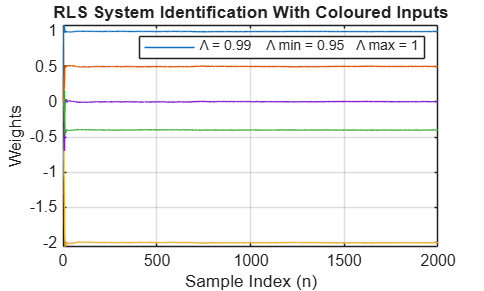


figure;
plot(0:N, rls_weights_ensemble.');
grid on;
title('RLS System Identification With Coloured Inputs');
xlabel('Sample Index (n)'); ylabel('Weights');
legend(['\Lambda = ' num2str(lamda_init) , '    ' ,  ...
        '\Lambda min = ' num2str(lamda_min), '   ' , ...

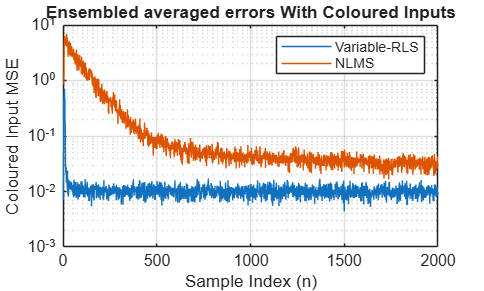

        '\Lambda max = ' num2str(lamda_max)])

figure;
semilogy(1:N, e_ensemble_rls, 1:N, e_ensemble_nlms);
grid on;
xlim([0, N]);
title('Ensembled averaged errors With Coloured Inputs');
xlabel('Sample Index (n)'); ylabel('Coloured Input MSE');
legend('Variable-RLS', 'NLMS');